close all;
mydata = load('RSdata.mat')

mydata = struct with fields:
               rt_tout: [3738×1 double]
         rt_ScopeData3: [1×1 struct]
            rt_v_drone: [1×1 struct]
          rt_phi_drone: [1×1 struct]
         rt_ScopeData2: [1×1 struct]
         rt_ScopeData1: [1×1 struct]
        rt_theta_drone: [1×1 struct]
            rt_u_drone: [1×1 struct]
                  rt_r: [1×1 struct]
                  rt_q: [1×1 struct]
            rt_noisy_q: [1×1 struct]
                  rt_p: [1×1 struct]
      rt_phi_drone_est: [1×1 struct]
    rt_theta_drone_est: [1×1 struct]
                rt_a_y: [1×1 struct]
                rt_a_x: [1×1 struct]
                rt_a_z: [1×1 struct]
                  rt_u: [1×1 struct]
                  rt_v: [1×1 struct]
                  rt_w: [1×1 struct]
        rt_v_drone_est: [1×1 struct]
        rt_u_drone_est: [1×1 struct]
       rt_z_ultrasonic: [1×1 struct]
           rt_pressure: [1×1 struct]




u = mydata.rt_u_drone.signals.values

u = 3738×1 single column vector
         0
    0.0027
    0.0052
    0.0077
    0.0100
    0.0122
    0.0144
    0.0180
    0.0216
    0.0251


u_est = mydata.rt_u_drone_est.signals.values

u_est =     0.0539
    0.0539
    0.0534
    0.0525
    0.0525
    0.0525
    0.0845
    0.0845
    0.0845
    0.1069


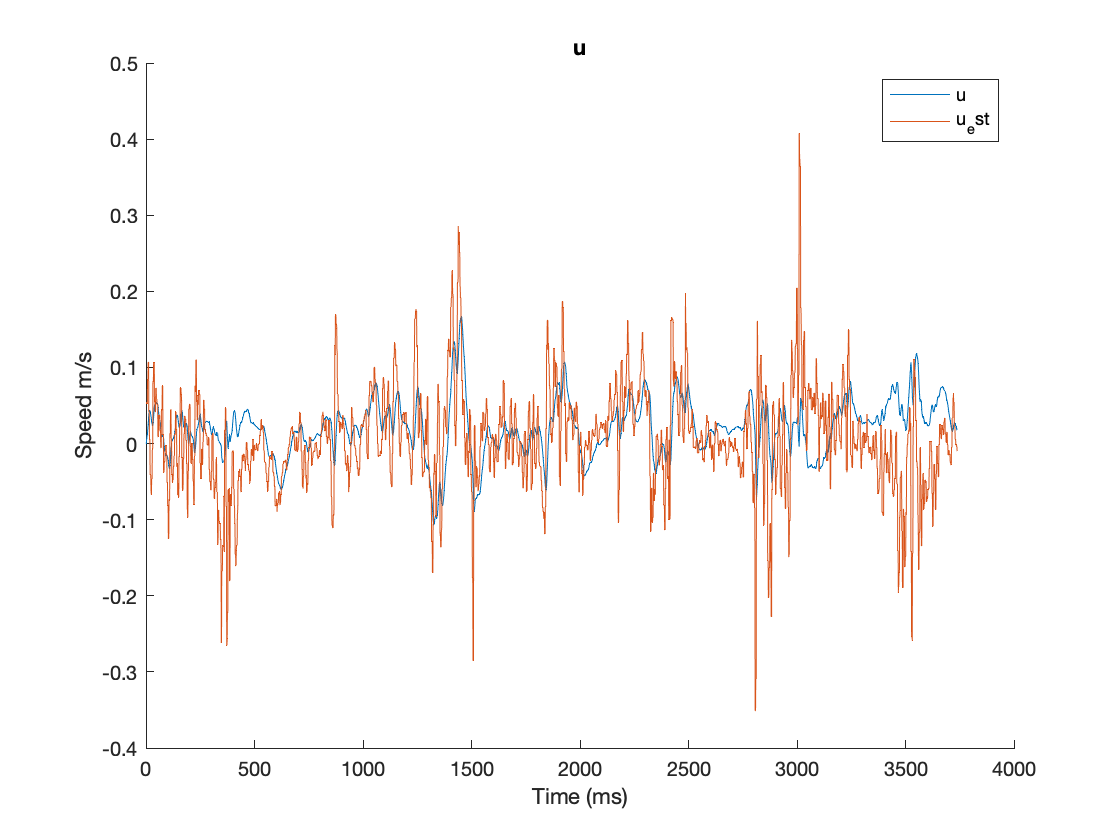


figure;
hold on;
plot(u);
plot(u_est)
xlabel("Time (ms)");
ylabel("Speed m/s");
title("u");
legend('u','u_est')
set(gcf,'Visible','on')



v = mydata.rt_v_drone.signals.values

v = 3738×1 single column vector
         0
    0.0024
    0.0048
    0.0070
    0.0104
    0.0136
    0.0168
    0.0199
    0.0229
    0.0259


v_est = mydata.rt_v_drone_est.signals.values

v_est =     0.1331
    0.1331
    0.1319
    0.2275
    0.2275
    0.2275
    0.2233
    0.2233
    0.2233
    0.2074


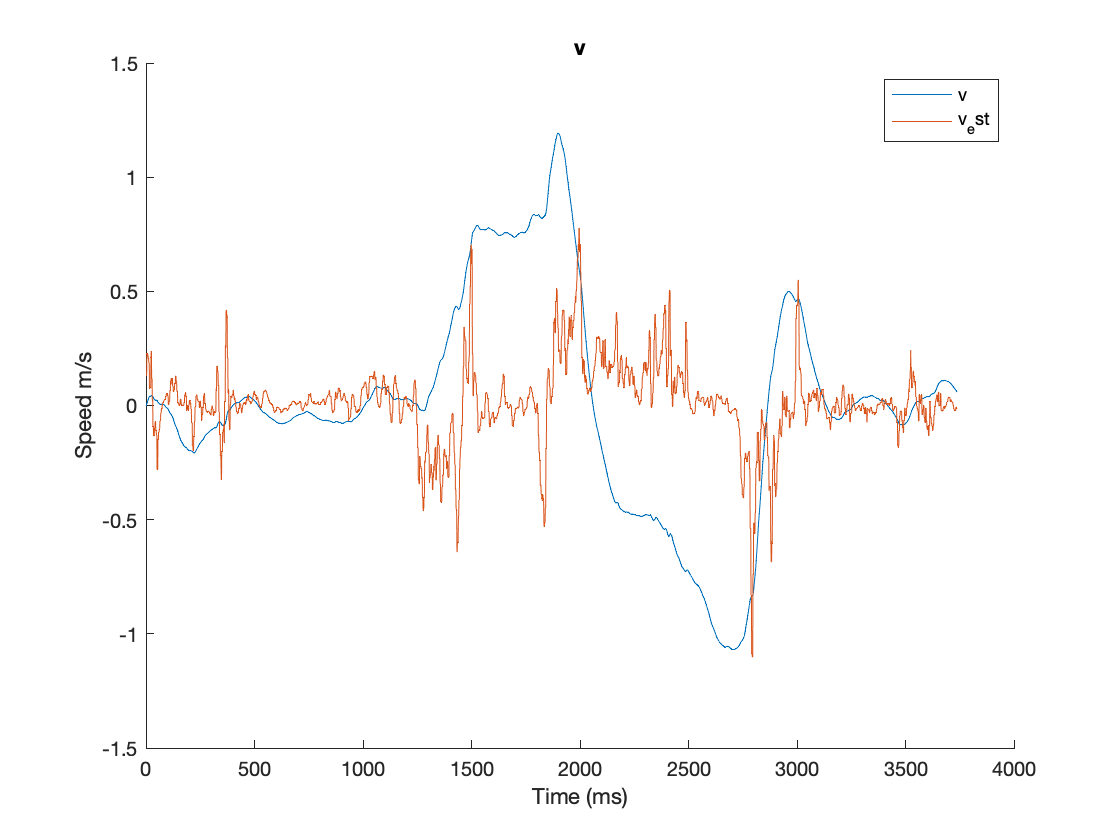


figure;
hold on;
plot(v);
plot(v_est);
xlabel("Time (ms)");
ylabel("Speed m/s");
title("v");
legend('v','v_est')
set(gcf,'Visible','on')



phi = mydata.rt_phi_drone.signals.values

phi = 3738×1 single column vector
         0
    0.0010
   -0.0002
   -0.0014
   -0.0021
   -0.0027
   -0.0032
   -0.0037
   -0.0041
   -0.0043


phi_est = mydata.rt_phi_drone_est.signals.values

phi_est = 3738×1 single column vector
    0.1881
    0.1827
    0.1834
    0.1889
    0.1968
    0.2069
    0.2157
    0.2176
    0.2132
    0.2139


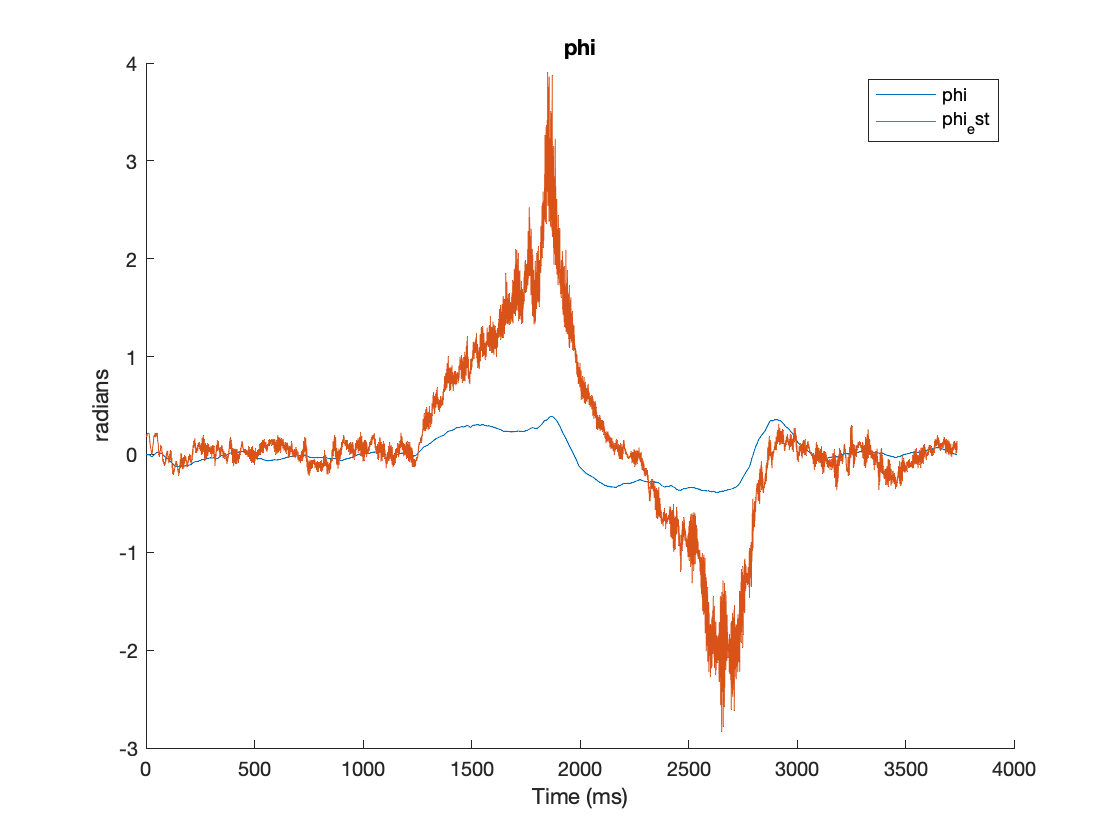

figure;
hold on;
plot(phi);
plot(phi_est)
xlabel("Time (ms)");
ylabel("radians");
title("phi");
legend('phi','phi_est')
set(gcf,'Visible','on')



theta = mydata.rt_theta_drone.signals.values

theta = 3738×1 single column vector
         0
   -0.0020
   -0.0023
   -0.0028
   -0.0036
   -0.0048
   -0.0063
   -0.0095
   -0.0130
   -0.0168


theta_est = mydata.rt_theta_drone_est.signals.values

theta_est = 3738×1 single column vector
   -0.2156
   -0.2267
   -0.2401
   -0.2484
   -0.2640
   -0.2772
   -0.2910
   -0.3025
   -0.3067
   -0.3015


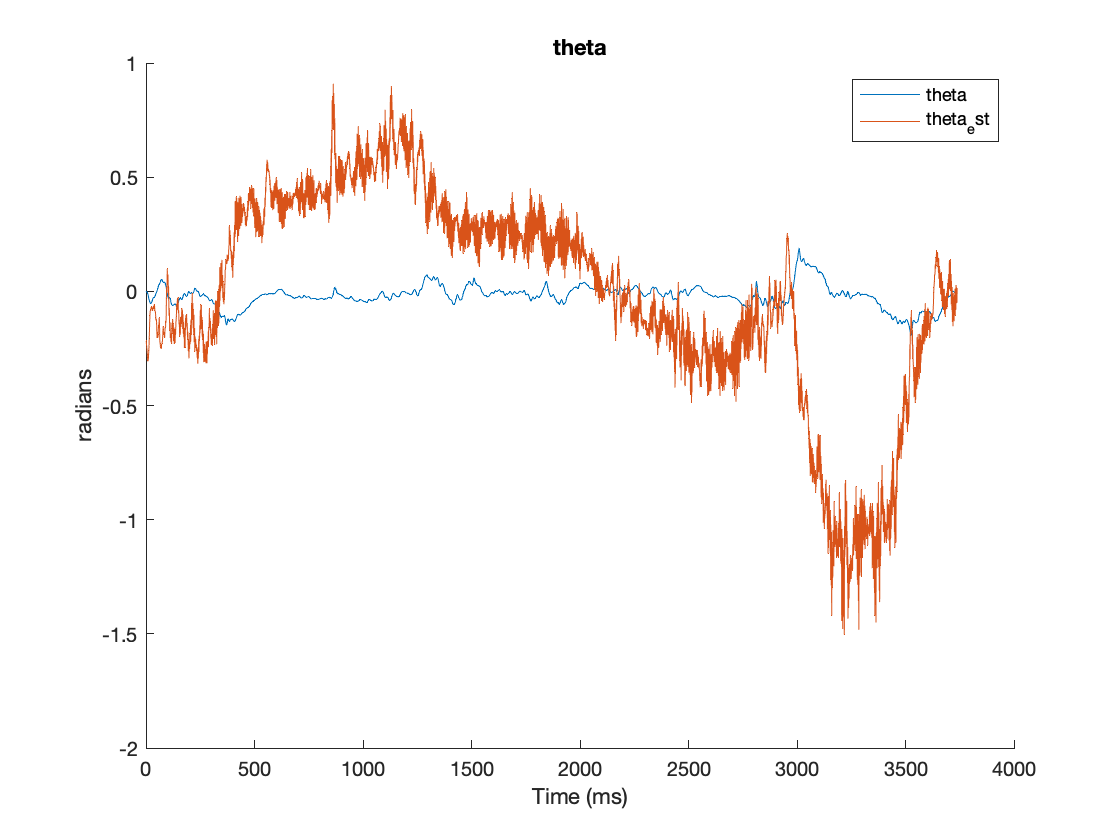

figure;
hold on;
plot(theta);
plot(theta_est)
xlabel("Time (ms)");
ylabel("radians");
title("theta");
legend('theta','theta_est')

set(gcf,'Visible','on')